x1 = @(f) 100e-6*250e-3*sinc(f*100e-6)*exp((-1i*pi*f*100e-6/2))

x1 = function_handle with value:
    @(f)100e-6*250e-3*sinc(f*100e-6)*exp((-1i*pi*f*100e-6/2))


x2 = @(f) 200e-6*500e-3*sinc(f*200e-6)*exp((-1i*pi*f*(100e-6/2+100e-6)))

x2 = function_handle with value:
    @(f)200e-6*500e-3*sinc(f*200e-6)*exp((-1i*pi*f*(100e-6/2+100e-6)))


x3 = @(f) 100e-6*250e-3*sinc(f*100e-6)*exp((-1i*pi*f*(100e-6/2+300e-6)))

x3 = function_handle with value:
    @(f)100e-6*250e-3*sinc(f*100e-6)*exp((-1i*pi*f*(100e-6/2+300e-6)))


x4 = @(f) -100e-6*250e-3*sinc(f*100e-6)*exp((-1i*pi*f*(100e-6/2+500e-6)))

x4 = function_handle with value:
    @(f)-100e-6*250e-3*sinc(f*100e-6)*exp((-1i*pi*f*(100e-6/2+500e-6)))


x5 = @(f) -200e-6*500e-3*sinc(f*200e-6)*exp((-1i*pi*f*(100e-6/2+600e-6)))

x5 = function_handle with value:
    @(f)-200e-6*500e-3*sinc(f*200e-6)*exp((-1i*pi*f*(100e-6/2+600e-6)))


x6 = @(f) -100e-6*250e-3*sinc(f*100e-6)*exp((-1i*pi*f*(100e-6/2+800e-6)))

x6 = function_handle with value:
    @(f)-100e-6*250e-3*sinc(f*100e-6)*exp((-1i*pi*f*(100e-6/2+800e-6)))


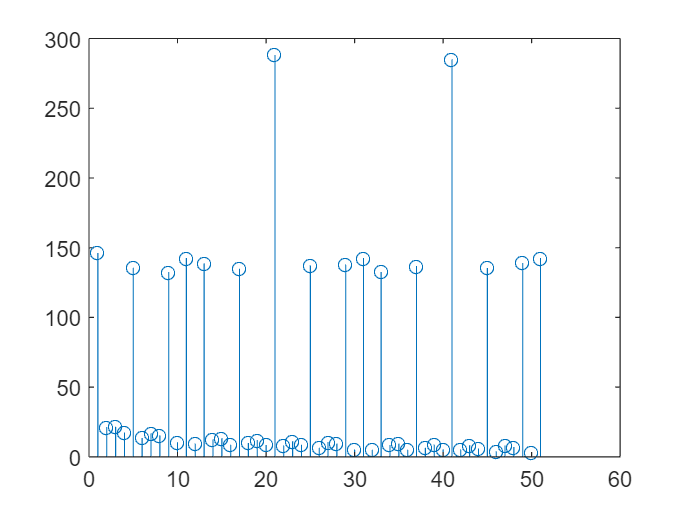

X = zeros(51,1);
for n=0:50
 temp = x1(n*1000)+x2(n*1000)+x3(n*1000)+x4(n*1000)+x5(n*1000)+x6(n*1000);
 temp = abs(temp)*1000;
 X(n+1) = 10*log10(1000*temp/sqrt(2));

 if(X(n+1)== -Inf)
     X(n+1) = -90;
 end
end

stem(abs(X))

## sin redressé

x1 = @(f) 50e-6*150e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*50e-6/2))

x1 = function_handle with value:
    @(f)50e-6*150e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*50e-6/2))


x2 = @(f) 50e-6*300e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+50e-6)))

x2 = function_handle with value:
    @(f)50e-6*300e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+50e-6)))


x3 = @(f) 50e-6*470e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+100e-6)))

x3 = function_handle with value:
    @(f)50e-6*470e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+100e-6)))


x4 = @(f) 100e-6*500e-3*sinc(f*100e-6)*exp(-(-1i*pi*f*(100e-6/2+150e-6)))

x4 = function_handle with value:
    @(f)100e-6*500e-3*sinc(f*100e-6)*exp(-(-1i*pi*f*(100e-6/2+150e-6)))


x5 = @(f) 50e-6*470e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+250e-6)))

x5 = function_handle with value:
    @(f)50e-6*470e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+250e-6)))


x6 = @(f) 50e-6*300e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+300e-6)))

x6 = function_handle with value:
    @(f)50e-6*300e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+300e-6)))


x7 = @(f) 50e-6*150e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+450e-6)))

x7 = function_handle with value:
    @(f)50e-6*150e-3*sinc(f*50e-6)*exp(-(-1i*pi*f*(50e-6/2+450e-6)))


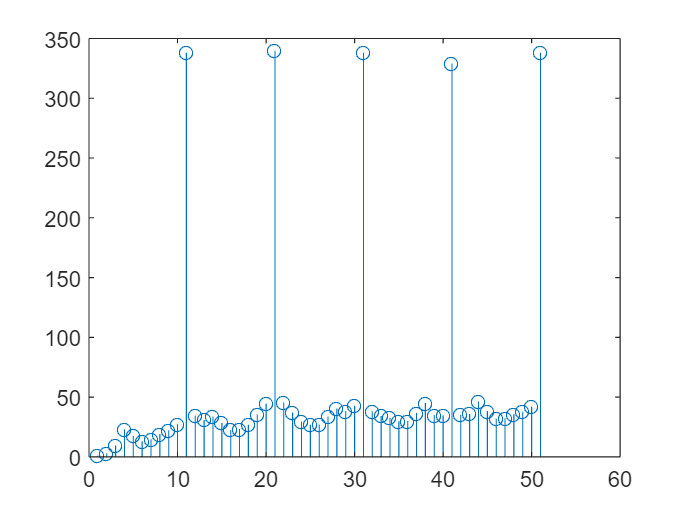


X = zeros(51,1);
for n=0:50
 temp = x1(n*2000)+x2(n*2000)+x3(n*2000)+x4(n*2000)+x5(n*2000)+x6(n*2000)+x7(n*2000);
 temp = abs(temp)*2000;
 X(n+1) = 10*log10((temp/sqrt(2))^2/(50e-3));

 if(X(n+1)== -Inf)
     X(n+1) = -90;
 end
end

stem(abs(X))